# Sampled Feedback System for 2 DoF Manipulator

Add Path

clear;clc;
close all
addpath("Dynamics\")
addpath("..\")
addpath("..\ReadYAML\")
Robot=ReadYaml("Configuration\Jiang.yaml");
config=ReadYaml("Configuration\2DoF_Manipulator.yaml");

The system follows


$$M\left(\vec{q}\right) \ddot{\vec{q}} + C \left( \vec{q}, \dot{\vec{q}} \right) \dot{\vec{q}} + G \left( \vec{q} \right) = - K_{p} \left( \vec{q} - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} - f \left( \dot{\vec{q}} \right),$$


where friction follows the Stribeck model as


$$f(\dot{q}_{j})= \mathrm{sgn} \left( \dot{q}_{j} \right) \cdot \left[ F_{j}^{c} + F_{j}^{s} \exp{\left( - K_{j}^{s} \frac{\dot{q}_{j}}{V_{j}^{s}} \right)} \right] + F_{j}^{v} \dot{q}_{j}.$$


## Configurations

SolverOpt

SolverOpt.initial_condition=config.StateInitial';
% SolverOpt.end_time=config.SimulationTime;
SolverOpt.end_time=5;
% SolverOpt.sampling_time=config.ts;
SolverOpt.sampling_time=0.0192;
SolverOpt.ratio=config.ratio;
SolverOpt.ode_setting=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

Other parameters

TargetAngle=config.TargetAngle';
Kp=diag(config.Kp);
Kd=diag(config.Kd);

## Digital Feedback Control Case

System ODE and Input Function

SysODE=@(t,State,Torque)feval("ODE",t,State,Robot,"Sigmoid",Torque);
InputFun=@(state)feval("PDTorque",Kp,Kd,Robot,state,TargetAngle);

Simulation

sol=SampledControlSolver(SysODE,InputFun,SolverOpt)

历时 2.275106 秒。


sol = 包含以下字段的 struct :
                  ts: 0.0192
                 dim: 2
                  dt: 1.9200e-05
    sampling_moments: [1×261 double]
            duration: [1×260417 double]
       state_history: [4×260417 double]
       state_sampled: [4×261 double]
       input_history: [2×260417 double]


% sol.state_history(:,end)
% sol.input_history(:,end)

### Visualization for Digital Time Control

Collect Data for Visualization

eTimeHistoryDigital=sol.state_history(1:2,:)-TargetAngle;

$e-t$ Diagram

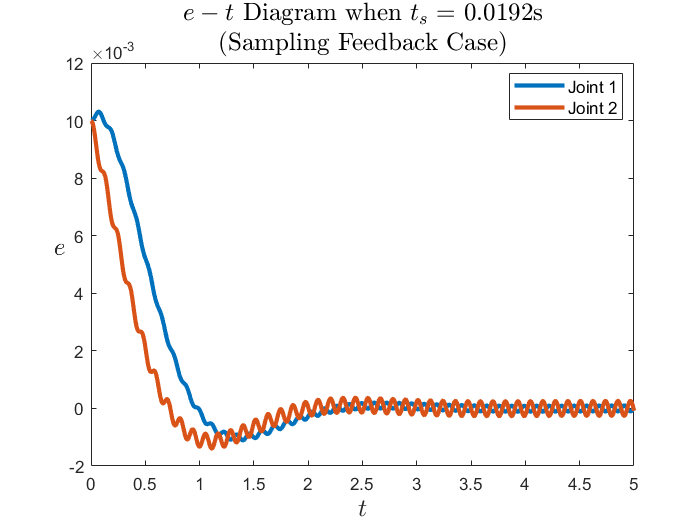

plot(sol.duration,eTimeHistoryDigital,"LineWidth",2.5)
title(["$$e-t$$ Diagram when $$t_s=$$ "+num2str(sol.ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

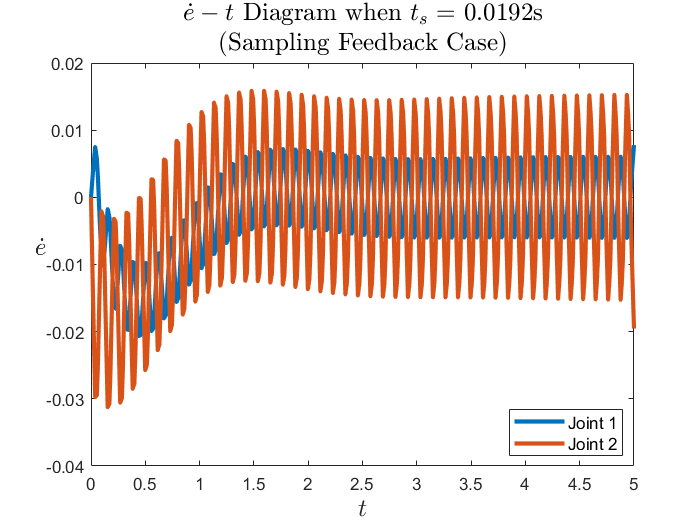

plot(sol.duration,sol.state_history(3:4,:),"LineWidth",2.5)
title(["$$\dot{e}-t$$ Diagram when $$t_s=$$ "+num2str(sol.ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

$\tau-t$ Diagram

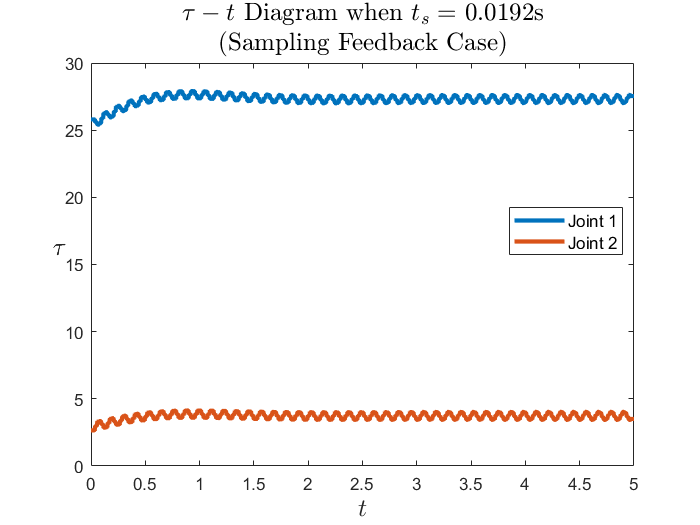

plot(sol.duration,sol.input_history,"LineWidth",2.5)
title(["$$\tau-t$$ Diagram when $$t_s=$$ "+num2str(sol.ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

% plot(sol.duration(1:5000),sol.input_history(:,1:5000))
% xline(sol.ts*(1:5),"r--")